# Laboratorium 10

### Filtracja sygnałów, Filtry FIR

Janusz Pawlicki

## 1. Wstęp

Filtracja jest procesem przetwarzania sygnału w dziedzinie czasu. Polega na redukowaniu (odfiltrowaniu) niepożądanych składowych zawartych w sygnale wejściowym. Filtracja to usuwanie szumu z sygnału/obrazu. Intuicyjnie szum jest stochastycznym odchyleniem sygnału od jego wartości rzeczywistej. Zadaniem filtracji jest eliminacja tego szumu głównie za pomocą metod przetwarzania sygnału/obrazu. W procesie przetwarzania filtry wykorzystywane są między innymi do:

- poprawy złej jakości technicznej sygnału,

- korekcji określonych wad sygnału,

- wzmocnienia w sygnale pewnych elementów zgodnych z posiadanym wzorcem,

- stłumienia w sygnale niepożądanego szumu,

- rekonstrukcji poszczególnych fragmentów sygnału, które uległy częściowemu uszkodzeniu.

Ze względu na typ przetwarzanych sygnałów filtrację dzieli się na:

- Analogową

- Cyfrową

Ze względu na sposób przetwarzania sygnału, filtry cyfrowe dzieli się na:

- Filtry FIR

- Filtry IIR

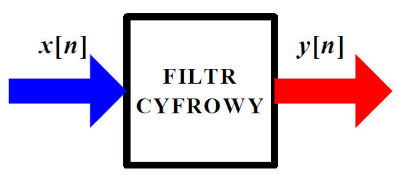

## 2.Przykłady

### 2.2

clear;
Przyklad_2

### 2.3

clear;
Przyklad_3

### 2.4

clear;
Przyklad_4

### 2.5

clear;
Przyklad_5

### 2.6

clear;
Przyklad_6

### 2.7

clear;
Przyklad_7

### 2.8

clear;
Przyklad_8

## 3. Zadania

### 3.1 

Korzystając z Przykładu 2 zaprojektować filtr wycinający składowe częstotliwości od 50-70 Hz.

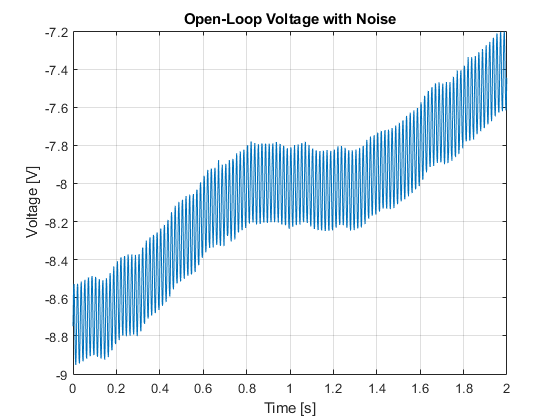

clear;
figure
load openloop60hertz, openLoop = openLoopVoltage;
Fs=1000;
t=(0:length(openLoop)-1)/Fs;
plot(t, openLoop); box on; grid on;
ylabel 'Voltage [V]', xlabel 'Time [s]'
title('Open-Loop Voltage with Noise')

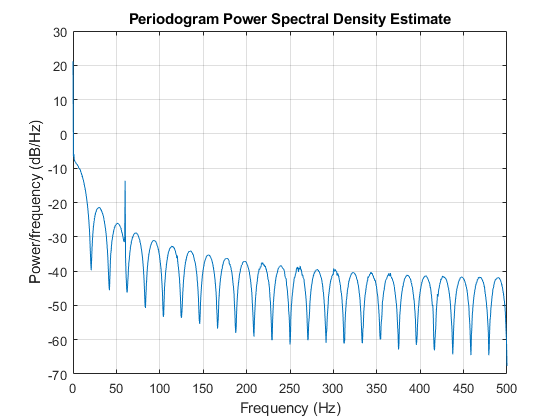


figure;
periodogram(openLoop, [], [], Fs);

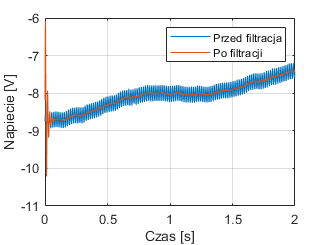


%Projekt flitra
filtCoeff = designfilt('bandstopiir', 'FilterOrder', 2,...
'HalfPowerFrequency1', 49, 'HalfPowerFrequency2', 71,...
'SampleRate', Fs);

%Wykres filtru
fvtool(filtCoeff)
noiseFreeSignal = filter(filtCoeff, openLoop);

close all
figure;

% Wynik w dziedzinie czasu
plot(t, openLoop, t, noiseFreeSignal); grid on;
legend('Przed filtracja', 'Po filtracji');
ylabel('Napiecie [V]'), xlabel('Czas [s]');

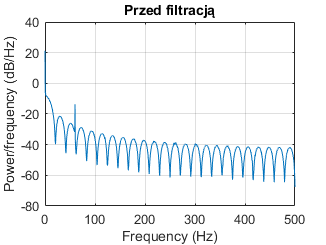


%Wynik w dziedzinie czestotliwosci
figure;
periodogram(openLoop, [], [], Fs);
title('Przed filtracją');

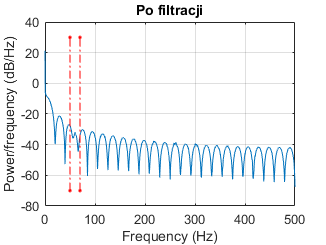


figure, hold on;
periodogram(noiseFreeSignal, [], [], Fs);
title('Po filtracji');
plot([50 50], [-70 30], 'r.-.');
plot([70 70], [-70 30], 'r.-.');
hold off;

### 3.2

Zaprojektować filtr o transmitancji:

Dla ciągu `x=[1, 2, 3, 4, 5, 4, 3, 4, 5, 6, 7]`

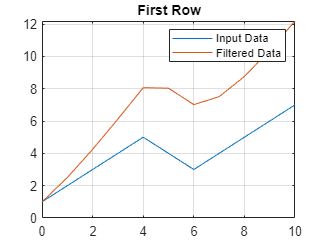

clear;
x = [1, 2, 3, 4, 5, 4, 3, 4, 5, 6, 7];

b = 1;
a = [1, -0.5];
y = filter(b, a, x, [], 2);
t = 0:length(x)-1; %indeks wektora

close all
plot(t, x(1, :));
hold on;
grid on;
plot(t, y(1,:))
legend('Input Data', 'Filtered Data')
title('First Row')

### 3.3

Zaprojektować filtr o transmitancji:

dla ciągu `x=[1, 2, 3, 4, 5, 4, 3, 4, 5, 6, 7]`

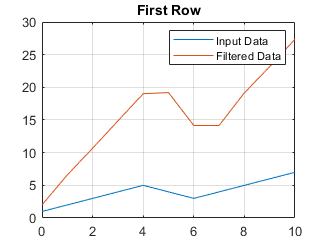

clear;
x = [1, 2, 3, 4, 5, 4, 3, 4, 5, 6, 7];

b = [2, 3];
a = [1, 0.2];
y = filter(b, a, x, [], 2);
t = 0:length(x)-1; %indeks wektora

close all
plot(t, x(1, :));
hold on;
grid on;
plot(t, y(1,:))
legend('Input Data', 'Filtered Data')
title('First Row')

### 3.4

Na podstawie przykładu 4 zaprojektować filtr dolnoprzepustowy. Wczytać sygnał chirp. Filtr odcina wysokie częstotliwości w 0,48. Pozostałe parametry jak okno Czebyszewa ustawić na 30 dB i sprawdzić jego działanie.

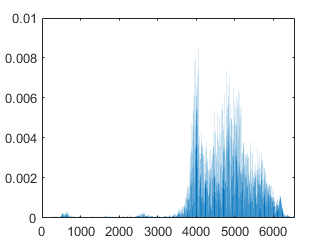

clear;
x = [1, 2, 3, 4, 5, 4, 3, 4, 5, 6, 7];

b = [2, 3];
a = [1, 0.2];
y = filter(b, a, x, [], 2);


load chirp;
Fs= 1000;
t = (0:length(y)-1)/Fs; %1.6 sekundy

xfft = abs(fft(y));
xfft = xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]);

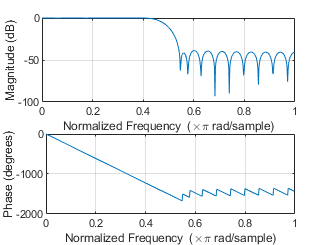


bhi = fir1(34, 0.48, 'low', chebwin(35, 30));
freqz(bhi,1)

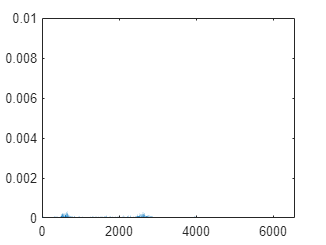

fvtool(bhi)
outhi=filter(bhi,1,y);

xfft=abs(fft(outhi));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]);

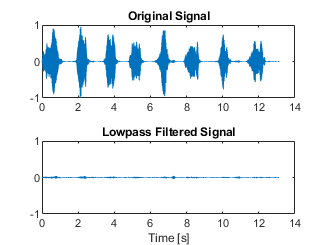


subplot(2,1,1)
plot(t,y);
title('Original Signal');
ys=ylim;

subplot(2,1,2)
plot(t, outhi)
title('Lowpass Filtered Signal');
xlabel('Time [s]');
ylim(ys);

### 3.5

Na podstawie przykładu 5 zaprojektować filtr, który będzie przepuszczać częstotliwości tłumione. Natomiast tłumić będzie te przepuszczane

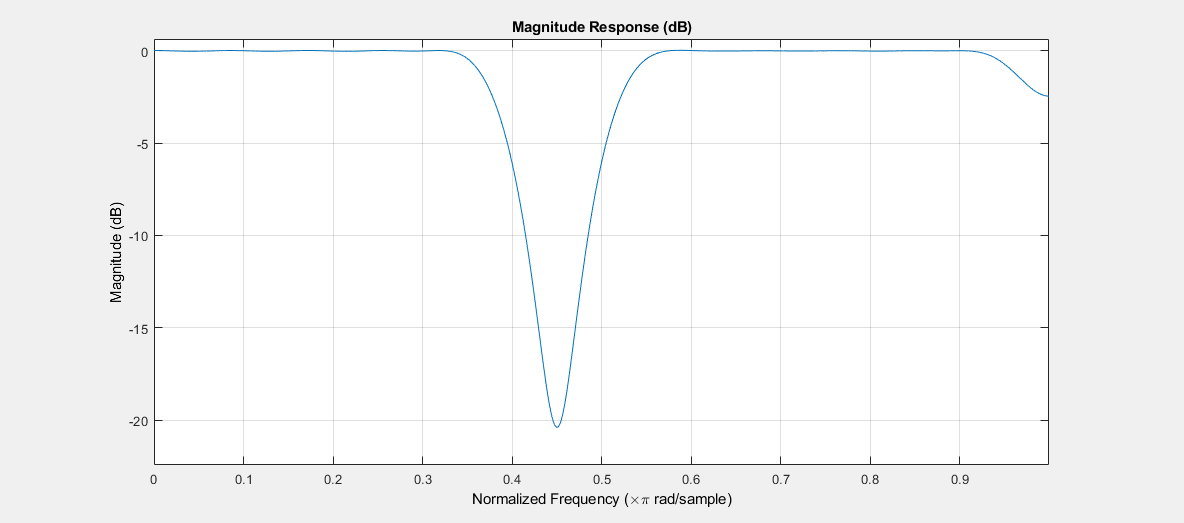

clear;
ord = 46;
low = 0.4;
bnd = [0.5 0.99];
bM = fir1(ord, [low bnd], 'DC-1');
fvtool(bM)

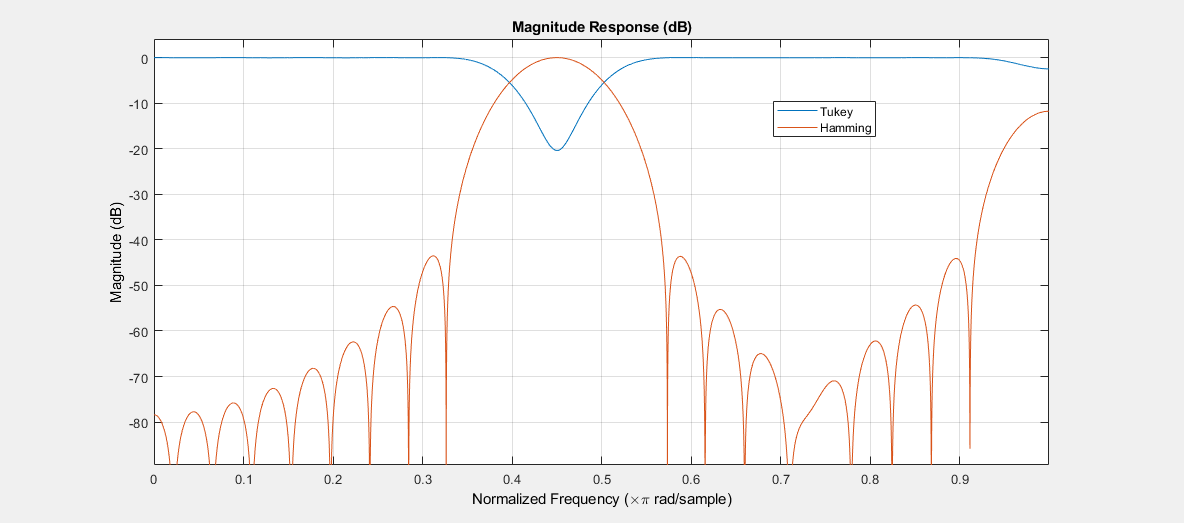



load chirp
t = (0:length(y)-1)/Fs;

hM = fir1(ord, [low bnd], 'DC-0', hann(ord+1));

hfvt = fvtool(bM,1,hM,1); %porownanie okien
legend(hfvt, 'Tukey', 'Hamming')

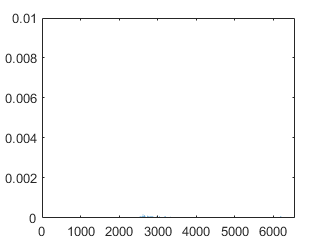


outhann = filter(hM, 1, y);

xfft=abs(fft(outhann)); 
xfft=xfft/13129; 
x1=1:1:6564; 
bar(x1(1:6564), xfft(1:6564));   
axis([0,6564, 0,0.01]) ;

### 3.6

Na podstawie przykładu 6 zaprojektować filtr, który używa okna Tukey (`'Tukey')`.Porównać filtry z oknem Hamminga (`'Hamming')` i Tukey.

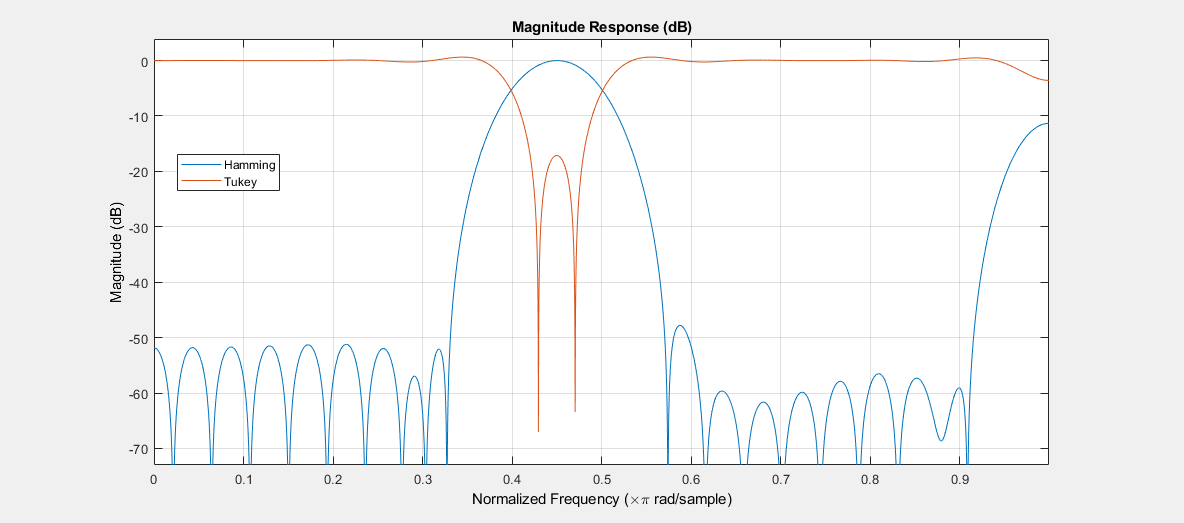

clear;
load chirp;
ord = 46;
low = 0.4;
bnd = [0.5 0.99];
bM = fir1(ord,[low bnd]);
tW = fir1(ord,[low bnd],'DC-1',tukeywin(ord+1));
hfvt = fvtool(bM,1,tW,1);
legend(hfvt,'Hamming','Tukey')

### 3.7

Korzystając z Przykładu 8, wyciąć składowe częstotliwości 500-1000 i przeprowadzić rozpoznawanie.

clear;
load wiatraki_przekladnie.mat
x2 = W20;
x3 = W21;
x4 = W23;
x5 = W24;
x6 = P20;
x7 = P21;
x8 = P23;
x9 = P24;

max_data=max(abs(W20));
data=W20/max_data;
xfft=abs(fft(x2));
xfft=xfft/44100;
xfft(501:999) = 0;

fid = fopen('FFT_wiatrak_20.txt','w+t','n');
fprintf(fid,'%f\n',xfft(1:22050));
fclose(fid);

max_data2=max(abs(W21));
data2=W21/max_data2;
xfft2=abs(fft(x3));
xfft2=xfft2/44100;
xfft2(501:999) = 0;

fid = fopen('FFT_wiatrak_21.txt','w+t','n');
fprintf(fid,'%f\n',xfft2(1:22050));
fclose(fid);

max_data3=max(abs(W23));
data3=W23/max_data3;
xfft3=abs(fft(x4));
xfft3=xfft3/44100;
xfft3(501:999) = 0;

fid = fopen('FFT_wiatrak_23.txt','w+t','n');
fprintf(fid,'%f\n',xfft3(1:22050));
fclose(fid);

max_data4=max(abs(W24));
data4=W24/max_data4;
xfft4=abs(fft(x5));
xfft4=xfft4/44100;
xfft4(501:999) = 0;

fid = fopen('FFT_wiatrak_24.txt','w+t','n');
fprintf(fid,'%f\n',xfft4(1:22050));
fclose(fid);

max_data5=max(abs(P20));
data5=P20/max_data5;
xfft5=abs(fft(x6));
xfft5=xfft5/44100;
xfft5(501:999) = 0;

fid = fopen('FFT_przekladnia_20.txt','w+t','n');
fprintf(fid,'%f\n',xfft5(1:22050));
fclose(fid);

max_data6=max(abs(P21));
data6=P21/max_data6;
xfft6=abs(fft(x7));
xfft6=xfft6/44100;
xfft6(501:999) = 0;

fid = fopen('FFT_przekladnia_21.txt','w+t','n');
fprintf(fid,'%f\n',xfft6(1:22050));
fclose(fid);

max_data7=max(abs(P23));
data7=P23/max_data7;
xfft7=abs(fft(x8));
xfft7=xfft7/44100;
xfft7(501:999) = 0;

fid = fopen('FFT_przekladnia_23.txt','w+t','n');
fprintf(fid,'%f\n',xfft7(1:22050));
fclose(fid);

max_data8=max(abs(P24));
data8=P24/max_data8;
xfft8=abs(fft(x9));
xfft8=xfft8/44100;
xfft8(501:999) = 0;

fid = fopen('FFT_przekladnia_24.txt','w+t','n');
fprintf(fid,'%f\n',xfft8(1:22050));
fclose(fid);

load FFT_przekladnia_20.txt
load FFT_przekladnia_21.txt
load FFT_przekladnia_23.txt
load FFT_przekladnia_24.txt
load FFT_wiatrak_20.txt
load FFT_wiatrak_21.txt
load FFT_wiatrak_23.txt
load FFT_wiatrak_24.txt

D1 = sum(abs(FFT_wiatrak_23-FFT_wiatrak_20));

D1 = 5.2154

D2 = sum(abs(FFT_wiatrak_23-FFT_wiatrak_21));

D2 = 5.1194

D3 = sum(abs(FFT_wiatrak_23-FFT_przekladnia_20));

D3 = 5.7627

D4 = sum(abs(FFT_wiatrak_23-FFT_przekladnia_21));

D4 = 5.7590

D5 = sum(abs(FFT_wiatrak_24-FFT_wiatrak_20));

D5 = 5.4113

D6 = sum(abs(FFT_wiatrak_24-FFT_wiatrak_21));

D6 = 5.2021

D7 = sum(abs(FFT_wiatrak_24-FFT_przekladnia_20));

D7 = 5.9198

D8 = sum(abs(FFT_wiatrak_24-FFT_przekladnia_21));

D8 = 5.9204

D9 = sum(abs(FFT_przekladnia_23-FFT_wiatrak_20));

D9 = 6.0206

D10 = sum(abs(FFT_przekladnia_23-FFT_wiatrak_21));

D10 = 6.0015

D11 = sum(abs(FFT_przekladnia_23-FFT_przekladnia_20));

D11 = 4.8495

D12 = sum(abs(FFT_przekladnia_23-FFT_przekladnia_21));

D12 = 4.6978

D13 = sum(abs(FFT_przekladnia_24-FFT_wiatrak_20));

D13 = 6.0213

D14 = sum(abs(FFT_przekladnia_24-FFT_wiatrak_21));

D14 = 5.8932

D15 = sum(abs(FFT_przekladnia_24-FFT_przekladnia_20));

D15 = 4.7183

D16 = sum(abs(FFT_przekladnia_24-FFT_przekladnia_21));

D16 = 4.9481

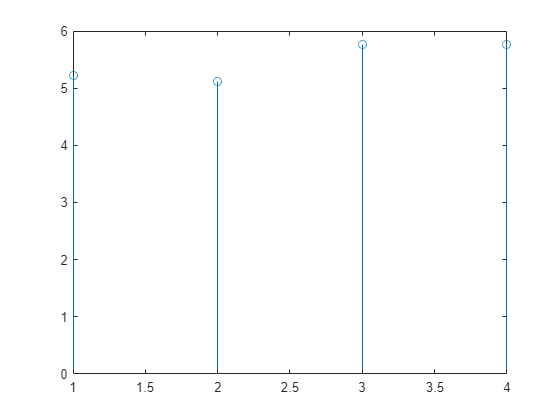


stem([D1 D2 D3 D4])

grid on

### 3.8

clear;
load wiatraki_przekladnie.mat
x2 = W20;
x3 = W21;
x4 = W23;
x5 = W24;
x6 = P20;
x7 = P21;
x8 = P23;
x9 = P24;

max_data=max(abs(W20));
data=W20/max_data;
xfft=abs(fft(x2));
xfft=xfft/44100;
xfft(101:1499) = 0;

fid = fopen('FFT_wiatrak_20.txt','w+t','n');
fprintf(fid,'%f\n',xfft(1:22050));
fclose(fid);

max_data2=max(abs(W21));
data2=W21/max_data2;
xfft2=abs(fft(x3));
xfft2=xfft2/44100;
xfft2(101:1499) = 0;

fid = fopen('FFT_wiatrak_21.txt','w+t','n');
fprintf(fid,'%f\n',xfft2(1:22050));
fclose(fid);

max_data3=max(abs(W23));
data3=W23/max_data3;
xfft3=abs(fft(x4));
xfft3=xfft3/44100;
xfft3(101:1499) = 0;

fid = fopen('FFT_wiatrak_23.txt','w+t','n');
fprintf(fid,'%f\n',xfft3(1:22050));
fclose(fid);

max_data4=max(abs(W24));
data4=W24/max_data4;
xfft4=abs(fft(x5));
xfft4=xfft4/44100;
xfft4(101:1499) = 0;

fid = fopen('FFT_wiatrak_24.txt','w+t','n');
fprintf(fid,'%f\n',xfft4(1:22050));
fclose(fid);

max_data5=max(abs(P20));
data5=P20/max_data5;
xfft5=abs(fft(x6));
xfft5=xfft5/44100;
xfft5(101:1499) = 0;

fid = fopen('FFT_przekladnia_20.txt','w+t','n');
fprintf(fid,'%f\n',xfft5(1:22050));
fclose(fid);

max_data6=max(abs(P21));
data6=P21/max_data6;
xfft6=abs(fft(x7));
xfft6=xfft6/44100;
xfft6(101:1499) = 0;

fid = fopen('FFT_przekladnia_21.txt','w+t','n');
fprintf(fid,'%f\n',xfft6(1:22050));
fclose(fid);

max_data7=max(abs(P23));
data7=P23/max_data7;
xfft7=abs(fft(x8));
xfft7=xfft7/44100;
xfft7(101:1499) = 0;

fid = fopen('FFT_przekladnia_23.txt','w+t','n');
fprintf(fid,'%f\n',xfft7(1:22050));
fclose(fid);

max_data8=max(abs(P24));
data8=P24/max_data8;
xfft8=abs(fft(x9));
xfft8=xfft8/44100;
xfft8(101:1499) = 0;

fid = fopen('FFT_przekladnia_24.txt','w+t','n');
fprintf(fid,'%f\n',xfft8(1:22050));
fclose(fid);

load FFT_przekladnia_20.txt
load FFT_przekladnia_21.txt
load FFT_przekladnia_23.txt
load FFT_przekladnia_24.txt
load FFT_wiatrak_20.txt
load FFT_wiatrak_21.txt
load FFT_wiatrak_23.txt
load FFT_wiatrak_24.txt

D1 = sum(abs(FFT_wiatrak_23-FFT_wiatrak_20));

D1 = 4.3973

D2 = sum(abs(FFT_wiatrak_23-FFT_wiatrak_21));

D2 = 4.3203

D3 = sum(abs(FFT_wiatrak_23-FFT_przekladnia_20));

D3 = 4.8252

D4 = sum(abs(FFT_wiatrak_23-FFT_przekladnia_21));

D4 = 4.8186

D5 = sum(abs(FFT_wiatrak_24-FFT_wiatrak_20));

D5 = 4.4681

D6 = sum(abs(FFT_wiatrak_24-FFT_wiatrak_21));

D6 = 4.4297

D7 = sum(abs(FFT_wiatrak_24-FFT_przekladnia_20));

D7 = 4.9671

D8 = sum(abs(FFT_wiatrak_24-FFT_przekladnia_21));

D8 = 4.9711

D9 = sum(abs(FFT_przekladnia_23-FFT_wiatrak_20));

D9 = 5.0348

D10 = sum(abs(FFT_przekladnia_23-FFT_wiatrak_21));

D10 = 5.0500

D11 = sum(abs(FFT_przekladnia_23-FFT_przekladnia_20));

D11 = 4.4286

D12 = sum(abs(FFT_przekladnia_23-FFT_przekladnia_21));

D12 = 4.3166

D13 = sum(abs(FFT_przekladnia_24-FFT_wiatrak_20));

D13 = 5.0311

D14 = sum(abs(FFT_przekladnia_24-FFT_wiatrak_21));

D14 = 4.9257

D15 = sum(abs(FFT_przekladnia_24-FFT_przekladnia_20));

D15 = 4.3151

D16 = sum(abs(FFT_przekladnia_24-FFT_przekladnia_21));

D16 = 4.5400

### 4. Pytania

#### 1) Co to jest filtracja sygnałów i po co ją stosujemy?

Filtracja to proces przetwarzania sygnału w dziedzinie czasu. Polega na redukowaniu niepożądanych składowych sygnału wejściowego. Główne zastosowania filtracji to odszumianie sygnału, jego „upiększanie” (np. w fotografii), korekcja wad sygnału lub jego rekonstrukcja.

#### 2) Co to jest filtr FIR i czym się charakteryzuje?

Jest to filtr nierekursywny o skończonej odpowiedzi impulsowej. Do uzyskania wyjściowej próbki sygnału używa tylko bieżącej oraz n przeszłych próbek wejściowych. Jego ważną cechą jest to, że podanie skończonej liczby próbek różnych od zera na wejście, na wyjściu również otrzymamy skończoną liczbę niezerowych próbek. 

#### 3) W jaki sposób projektujemy filtry FIR?

#### 4) Do czego służą okna?

Dzięki zastosowaniu okien zmniejszamy falowanie charakterystyki kosztem rozdzielczości. Ich zaletą jest niwelowanie błędów i otrzymanie okresowości, a także gwarantuje szybką transformację.